# Space Mechanics (086287) – HW1

Olga Ioffe

HW from semester: Winter 2017-18

Revised: Oct. 2024

Matlab ver.: 2024b

### Initialization

clear
close all
clc

### Constants

mu = 3.98603e5; %km^3/sec^2, from Appendix A
Re = 6378.16; %km

## Question 1

### Problem

Given:

T = 120*60; %sec

At descending node:

rx_d = 5300; %km
ry_d = 6100; %km

Vx_d = -1.5; %km/s
Vy_d = 2.2; %km/s

Find:

a. rz and Vz

b. a, e and inclination

### Solution

Descending Node =>

rz_d = 0;

From Time Period: 

a = (T^2*mu/4/pi^2)^(1/3);

From Energy Equation:

For Elliptical orbit:

En = -mu/2/a;

r_abs = norm([rx_d, ry_d, rz_d]);
V2 = 2 * (mu/r_abs + En);

At the descending node the z velocity component is negative

Vz_d = -sqrt(V2-Vx_d*Vx_d-Vy_d*Vy_d);

The Equation for Eccentricity:

Where h is the angular momentum:

 

h_vec = cross([rx_d,ry_d,rz_d],[Vx_d,Vy_d,Vz_d]);
h_abs = norm(h_vec);
e = sqrt(1+2*En*h_abs^2/mu^2);

Inclination is the angle between the angular momentum vector and the z axis:

inclination = acos(h_vec(3)/h_abs)*180/pi; %deg

Arrange the output

str_ans = sprintf(['Q1 answers\npart a:\n' ...
    'rz = %4.3f [km], Vz = %4.3f [km/s]\n'...
    'part b:\n'...
    'a = %4.0f[km], e = %5.4f, inclination = %5.3f[deg]'],...
    rz_d, Vz_d, a, e, inclination);
disp(str_ans)

Q1 answers
part a:
rz = 0.000 [km], Vz = -6.489 [km/s]
part b:
a = 8059[km], e = 0.0965, inclination = 68.353[deg]


## Question 2

### Problem

Given:

T = 2*3600; %sec
alt_perigee = 500; %km

Calculate total velocity change for:

a. two pulse transfer from perigee

b. two pulse transfer from apogee

c. ine pulse transfer at intersection

### Solution - precalculations

r_perigee_i = alt_perigee + Re;

Semimajor axis of initial and  radus of  target orbit:


$$T=2\pi\sqrt{a^3/\mu} \Rightarrow a=\left(\frac{T^2\mu}{4\pi^2}\right)^{1/3} $$


a = (T^2*mu/4/pi^2)^(1/3);

Velocity at a point on ellictic orbit:

(1) $\frac{V^2}{2}-\frac{\mu}{r}=En \Rightarrow V=\sqrt{2\left(\frac{\mu}{r}-\frac{\mu}{2a}\right)}$

Velocity of circular orbit:

(2) $V_c=\sqrt{\frac{\mu}{r}}$

### Solution a - transfer from perigee

Semimajor axis of transfer orbit from perigee:

It's apogee is the rads of the circular orbit.

aTp = (a+r_perigee_i)/2;

Using equations (1) and (2)

deltaV1 = sqrt(2*mu*(1/r_perigee_i-0.5/aTp))-sqrt(2*mu*(1/r_perigee_i-0.5/a))

deltaV1 = -0.2435

deltaV2 = sqrt(2*mu*(1/a-0.5/aTp))-sqrt(mu/a)

deltaV2 = -0.2837

deltaVtotal = abs(deltaV1)+abs(deltaV2)

deltaVtotal = 0.5272

Calculate other geometric parameters:

e_initial = 1 - r_perigee_i/a;
b_initial = a*sqrt(1-e_initial^2);
c_initial = e_initial*a;

e_transfer = 1 - r_perigee_i/aTp;
b_transfer = aTp*sqrt(1-e_transfer^2);
c_transfer = e_transfer*aTp;

Draw initial and target orbits:

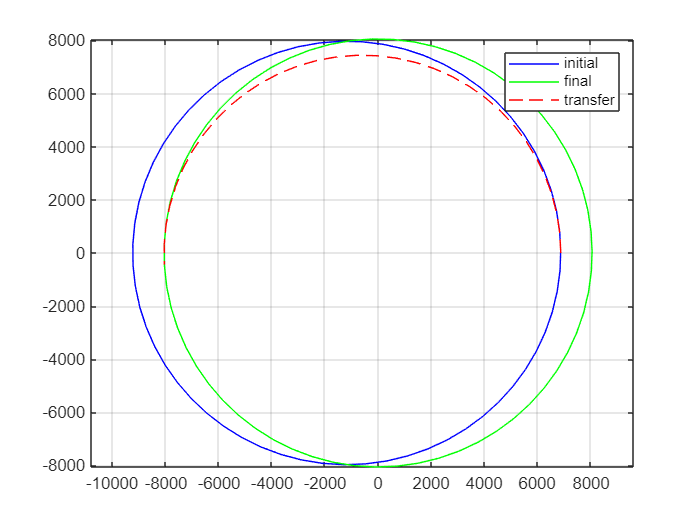

figure(1)

theta_vec_full = 0:.1:(2*pi+.1);
theta_vec_transfer = 0:.1:(pi+.1);

x_vec_initial = -c_initial+a*cos(theta_vec_full);
y_vec_initial = b_initial*sin(theta_vec_full);
plot(x_vec_initial,y_vec_initial,'b');
hold all

x_vec_circle = a*cos(theta_vec_full);
y_vec_circle = a*sin(theta_vec_full);
plot(x_vec_circle,y_vec_circle,'g');
hold all

x_vec_transfer = -c_transfer+aTp*cos(theta_vec_transfer);
y_vec_transfer = b_transfer*sin(theta_vec_transfer);
plot(x_vec_transfer,y_vec_transfer,'r--');
hold all

legend('initial','final','transfer')
grid
axis equal

### Solution b - transfer from apogee

Semimajor axis of transfer orbit from perigee:

It's perigee is the rads of the circular orbit.

r_apogee_i = 2*a - r_perigee_i;

aTa = (a+r_apogee_i)/2;

Using equations (1) and (2)

deltaV1 = sqrt(2*mu*(1/r_apogee_i-0.5/aTa))-sqrt(2*mu*(1/r_apogee_i-0.5/a))

deltaV1 = 0.2721

deltaV2 = sqrt(2*mu*(1/a-0.5/aTa))-sqrt(mu/a)

deltaV2 = 0.2361

deltaVtotal = abs(deltaV1)+abs(deltaV2)

deltaVtotal = 0.5082

Draw initial and target orbits:

figure(2)

Calculate other geometric parameters:

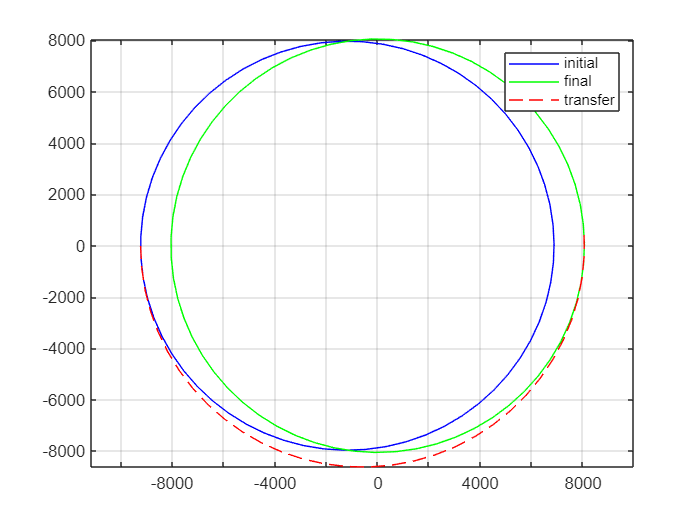

e_transfer = 1 - a/aTa;
b_transfer = aTa*sqrt(1-e_transfer^2);
c_transfer = e_transfer*aTa;

theta_vec_full = 0:.1:(2*pi+.1);
theta_vec_transfer = pi:.1:(2*pi+.1);

plot(x_vec_initial,y_vec_initial,'b');
hold all

plot(x_vec_circle,y_vec_circle,'g');
hold all

x_vec_transfer = -c_transfer+aTa*cos(theta_vec_transfer);
y_vec_transfer = b_transfer*sin(theta_vec_transfer);
plot(x_vec_transfer,y_vec_transfer,'r--');
hold all

legend('initial','final','transfer')
grid
axis equal

### Solution c - single pulse at intersection

At intersectionradius and semimajor axis of both orbits are equal. The velocity vector needs to be rotated by angle $\gamma$.

(2) $V_c=\sqrt{\frac{\mu}{r}}$

(3) $tan(\gamma) = \frac{e}{\sqrt{1-e^2}}$

(4) $\Delta V_{total} = 2Vsin(\gamma/2)$

V  = sqrt(mu/a)

V = 7.0328

gamma = atan(e_initial/sqrt(1-e_initial^2))

gamma = 0.1471

deltaVtotal = 2*V*sin(gamma/2)

deltaVtotal = 1.0333

## Question 3

Get expressions for radial and normal components of the velocity vector vs. the true anomaly angle, parameter p and ecsentricity e. Find the extremum valies and their positions on the orbit.

### Solution

In polar coordinates:

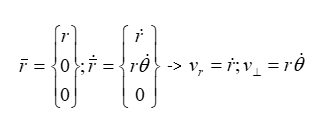

Differentiating the expression for r:

The differential of the angle:

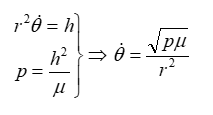

Therefore:

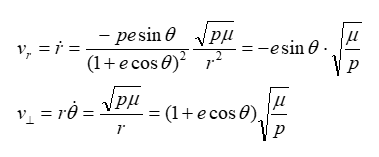

The extrema: